clear; close all;

# 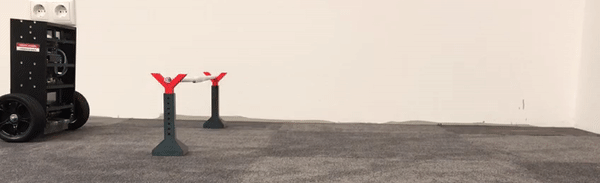

# Implementing the Planning Problem

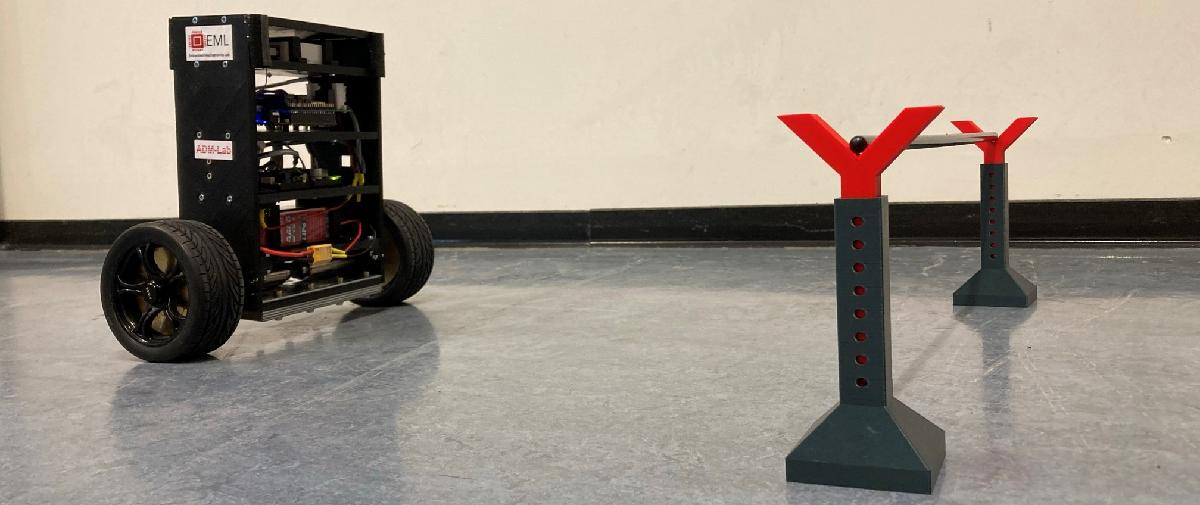

## Setting up the Real-World

#### The Configuration Space

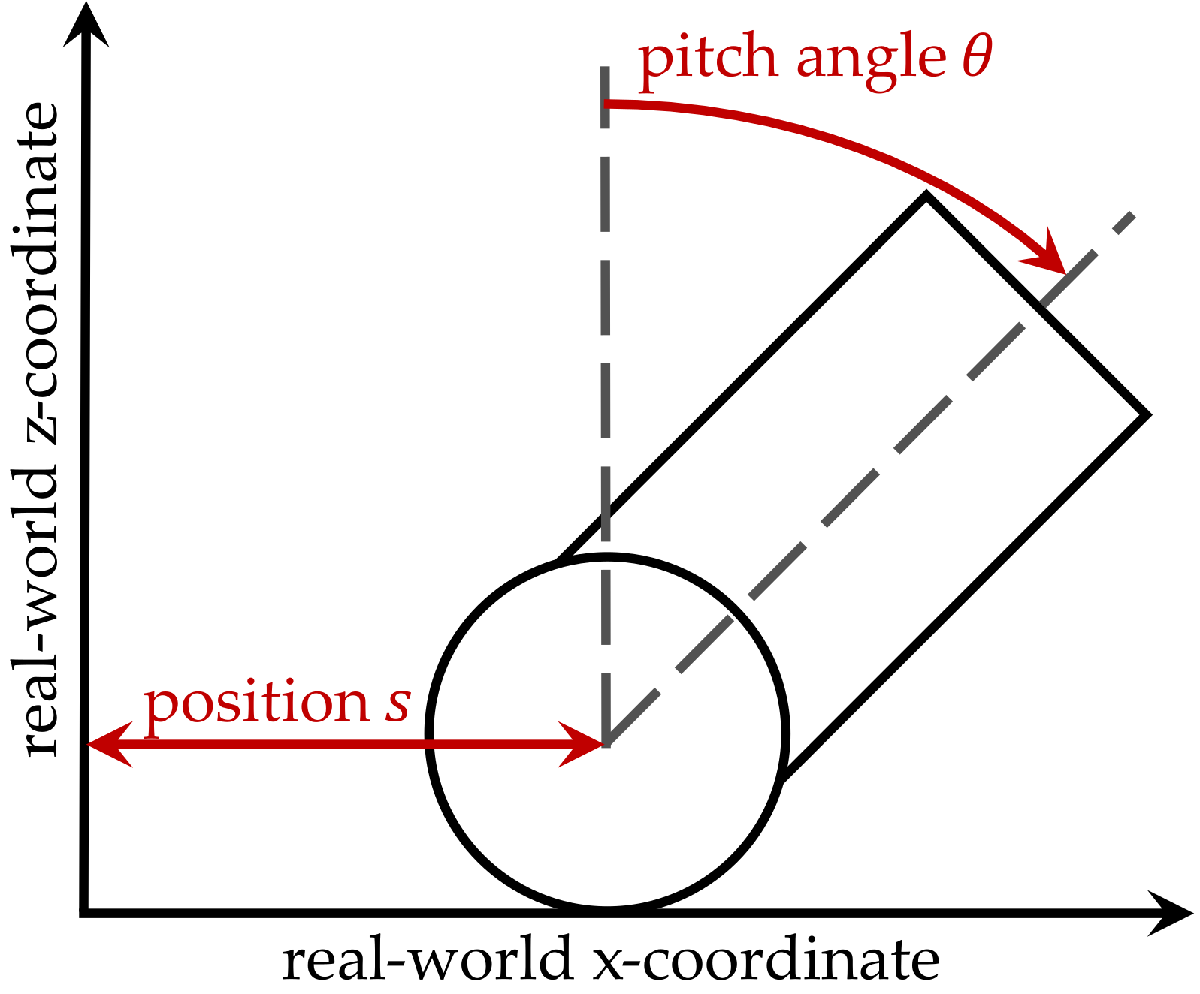

pitch_max    = deg2rad(90);
pitch_min    = deg2rad(-90);
position_max = 6;
position_min = -0.25;

#### Algebraic Model of Chabo

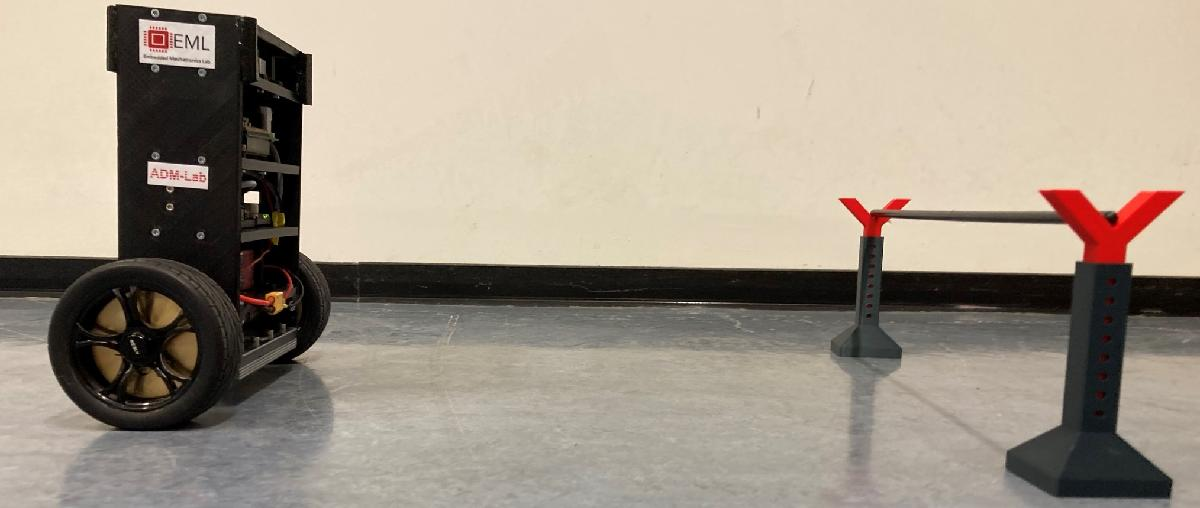

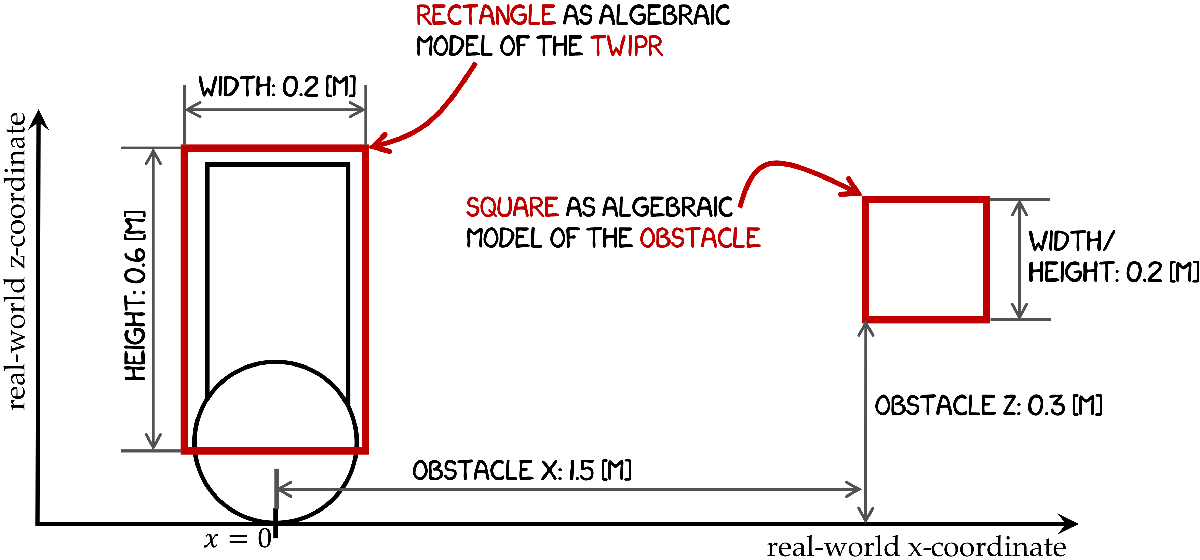

% Geometric sizes of the Chabo polygon
twipr_height = 0.6;
twipr_width  = 0.2;
twipr_wheel_radius = 0.1;

% Setup the vertices and the polygon of Chabo using the MATLAB-function
% "polyshape"
chabo_vertices_x_coordinates    = [twipr_width/2,...
                                  twipr_width/2,...
                                  -twipr_width/2,...
                                  -twipr_width/2];
chabo_vertices_z_coordinates    = [twipr_wheel_radius,...
                                  twipr_wheel_radius + twipr_height,...
                                  twipr_wheel_radius + twipr_height,...
                                  twipr_wheel_radius];
chabo_polygon                   = polyshape(chabo_vertices_x_coordinates, chabo_vertices_z_coordinates);

#### Putting everything together

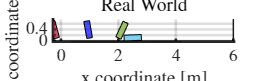

figure('Position', [0, 0, 700, 220]);
% Construct the real-world object that models and visualizes the geometry of the real world
real_world   = CRealWorld(pitch_max, pitch_min, position_max, position_min, chabo_polygon);
% Draw our real-wrold
real_world.drawWorld();
% Draw our TWIPR model
real_world.drawChabo(deg2rad(-10), 1, 'blue');
% Let's draw some more TWIPRs
real_world.drawChabo(deg2rad(25), 2);
real_world.drawChabo(deg2rad(88), 2.2);
real_world.drawChabo(deg2rad(-15), -0.15);

## Algebraic Model of the Obstacle

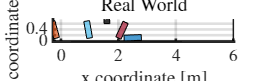

% Geometric sizes of the obstacle
obstacle_height     = 0.2;
obstacle_width      = 0.2;
obstacle_z_position = 0.6;
obstacle_x_position = 1.5;

% Setup the vertices and the polygon of the obstacle
obstacle_vertices_x_coordinates = [obstacle_x_position,...
                                 obstacle_x_position,...
                                 obstacle_x_position + obstacle_width,...
                                 obstacle_x_position + obstacle_width];
obstacle_vertices_z_coordinates = [obstacle_z_position,...
                                 obstacle_z_position + obstacle_height,...
                                 obstacle_z_position + obstacle_height,...
                                 obstacle_z_position];
obstacle_polygon                = polyshape(obstacle_vertices_x_coordinates, obstacle_vertices_z_coordinates);

% Add the obstacle to our real-world object
real_world.addObstacle(obstacle_polygon);
% Let's draw our new real-world with the obstacle and some TWIPRs
figure('Position', [0, 0, 700, 220]);
real_world.drawWorld();
real_world.drawChabo(deg2rad(-10), 1);
real_world.drawChabo(deg2rad(25), 2);
real_world.drawChabo(deg2rad(88), 2.2);
real_world.drawChabo(deg2rad(-15), -0.15);

## Collision Detection

figure('Position', [0, 0, 700, 220]);
real_world.drawWorld();
% Let's create some TWIPR configurations
y1 = [deg2rad(30); 0.7];
y2 = [deg2rad(-15); 0.1];
y3 = [deg2rad(60); 1.2];
y4 = [deg2rad(-30); 1.9];
y5 = [deg2rad(23); 2.5];

Y  = [y1, y2, y3, y4, y5];

% Iterate over the configurations
for n = 1:size(Y, 2)
    y = Y(:, n);
    % Check for a collision (using pre-programmed library function)
    collision_flag = real_world.checkConfigurationInCollision(y);
    if(collision_flag)
        % If we are in collision, draw the TWIPR in red
        real_world.drawTWIPR(y(1), y(2), 'red');
    else
        % If we are not in collision, draw the TWIPR in blue
        real_world.drawTWIPR(y(1), y(2), 'blue');
    end
end

## Creating a Configuration-Space-World

#### Setting up the C-Space World

% Let's draw a map of our configuration space
figure; axes;
% The x-axis is the robot's position
xlabel('position [m]');
xlim([position_min, position_max]);
% The y-axis is the robot's pitch angle
ylabel('pitch [deg]');
ylim([pitch_min, pitch_max]);


#### Determining a Polygon of the Obstacle in C-Space

% Number of samples per C-space coordinate
N = 30;
% Samples of the C-space coordinates
pitch_samples    = linspace(pitch_min, pitch_max, N);
position_samples = linspace(position_min, position_max, N);

% Allocate an array that contains all configurations that are in collision
Y_obstacle = [];
% Iterate over all possible combinations of pitch and position samples
for n_pitch = 1:N
    % pitch sample
    pitch = pitch_samples(n_pitch);
    for n_position = 1:N
        % position sample
        position = position_samples(n_position);
        % setup the configuration vector
        y = [pitch; position];
        % check for collision
        collision_flag = real_world.checkConfigurationInCollision(y);
        if(collision_flag)
            % if the configuration is in collision, plot a red point in
            % our c-space map
            line(y(2), y(1),'Marker', '.', 'LineWidth', 5, 'MarkerSize', 12, 'Color', 'red'); hold on;
            % and add the configuration to our obstacle-configuration-array
            Y_obstacle(:, end+1) = y;
        else
            % if the configuration is not in collision, plot a blue point
            % in our c-space map
            line(y(2), y(1),'Marker', '.', 'LineWidth', 5, 'MarkerSize', 12, 'Color', 'blue'); hold on;
        end
    end    
end

% Determine boundary polygon of the configurations using MATLAB-functions "boundary" and "polyshape" that are in collision
ind   = boundary(Y_obstacle(2,:)', Y_obstacle(1,:)'); 
obstacle_vertex_position_coordinates = Y_obstacle(2,ind);
obstacle_vertex_pitch_coordinates    = Y_obstacle(1,ind);
obstacle_polygon = polyshape(obstacle_vertex_position_coordinates,...
                             obstacle_vertex_pitch_coordinates);

% Let's plot our new obstacle polygon
plot(obstacle_polygon, 'FaceColor', [0.1, 0.1, 0.1]);

### Save the obstacle and real world objects for later use

save('1_Data\obstacles\obstacle.mat', 'obstacle_polygon');
% save('1_Data\real_world.mat', 'real_world');